**Giordano Dylan - Martelet Curtis                            M1 EEA Grp C**

# Rapport TP1: Hacheur Série & Parallèle

## 1. Hacheur Série

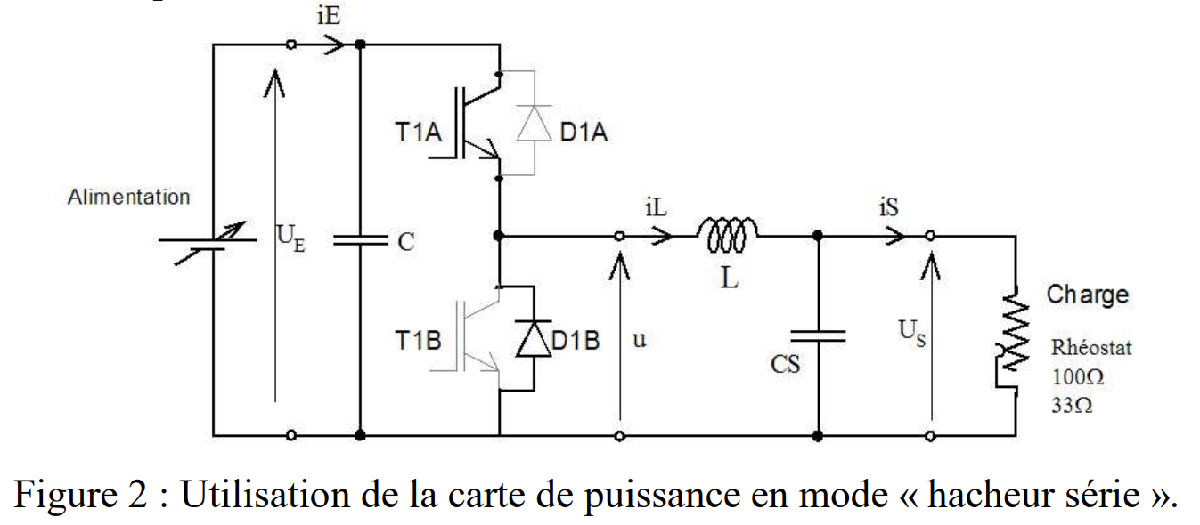

### Mesures de valeurs moyennes :

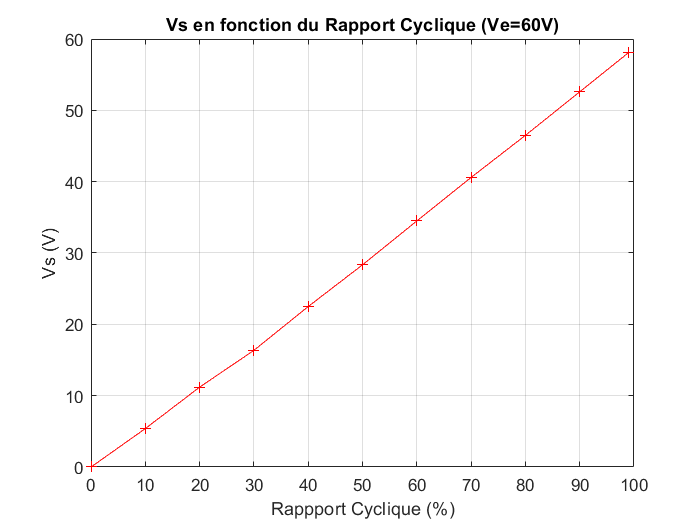

clear all;
Ve = 60;
rapport_cycle=[0 10 20 30 40 50 60 70 80 90 99];
Vs           =[0 5.39 11.2 16.36 22.5 28.35 34.5 40.6 46.5 52.6 58.1];
Ie           =[0 0.2 0.42 0.61 0.81 1.01 1.22 1.43 1.65 1.81 2];
Is           =2;       
plot(rapport_cycle,Vs,'r+-'); % Vs=f(alpha)
title('Vs en fonction du Rapport Cyclique (Ve=60V)')
xlabel('Rappport Cyclique (%)'); ylabel('Vs (V)')
grid on

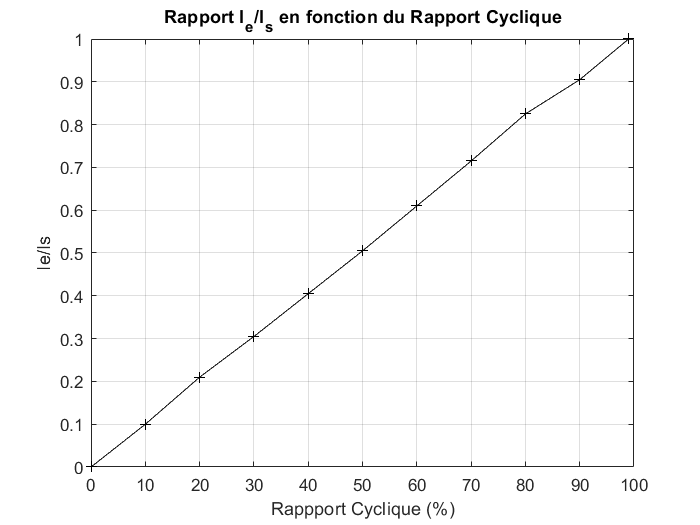

plot(rapport_cycle,Ie./Is,'k+-'); %%Ie/Is=f(alpha)
title('Rapport I_e/I_s en fonction du Rapport Cyclique')
xlabel('Rappport Cyclique (%)'); ylabel('Ie/Is')
grid on

Pour la premiere courbe, nous avons la relation Vs= α*Ve, la courbe obtenue est donc une droite.

Pour la seconde courbe, nous pouvons constater que le rapport des courants Ie/Is est proportionnel au rapport cyclique.

En effet, dans ce mode de fonctionnement, Pe=Ps donc nous avons la relation : Ie=( **α***Is).

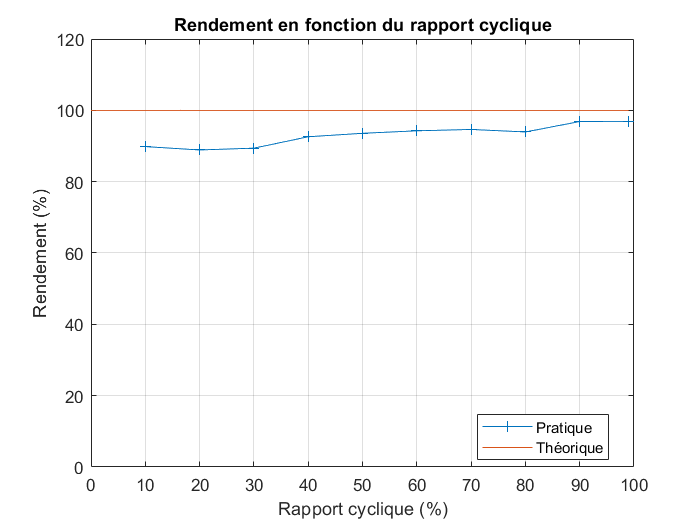

rendement_th=[100 100 100 100 100 100 100 100 100 100 100];
plot(rapport_cycle,((Vs.*Is)./(Ve.*Ie)) *100,'+-',rapport_cycle,rendement_th);
title("Rendement en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("Rendement (%)");
legend('Pratique','Théorique','Location','best');
ylim([0 120])
grid on;

Nous observons que le rendement est quasiment constant qu'importe la valeur du rapport cyclique.

### Mesures temporelles

Tracés Jaunes : Vs ; Tracés Verts : iL

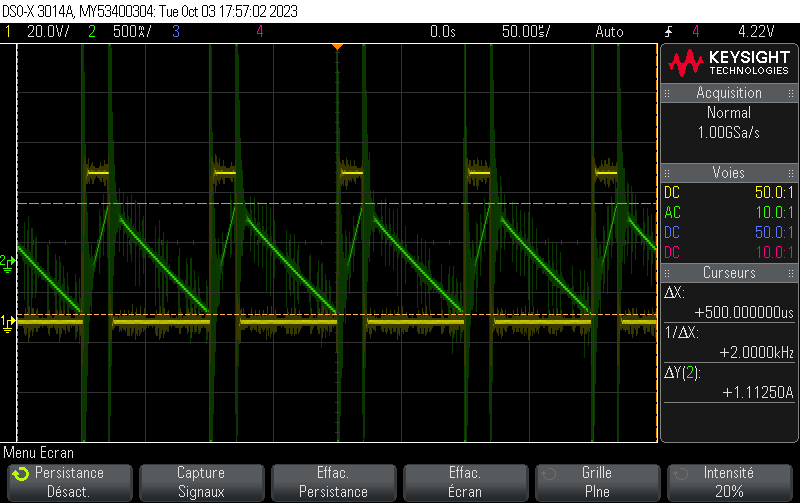

Rapport cyclique de 30%

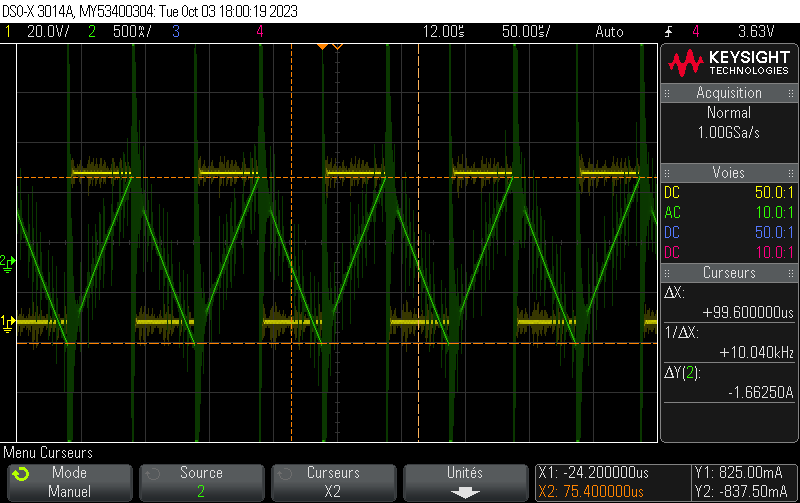

Rapport cyclique de 50%.

On observe sur les relevés d'oscilloscopes que le courant est croissant quand la tension n'est pas nulle (de 0 à alpha T), et décroissant quand la tension est nulle (de alpha T à T).

On observe égament que le courant iL est l'intégrale de la tension u, et que la valeur moyenne du courant iL est nul.

### Ondulation du courant iL:

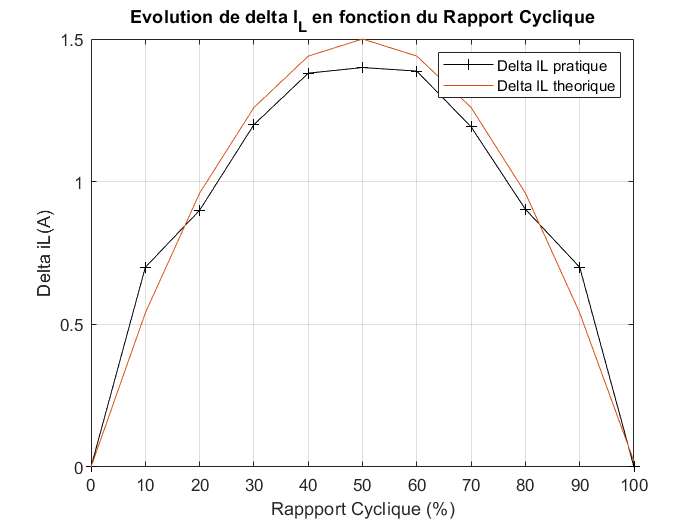

% Ondulation de courant Il
rapport_cycle=[100 90 80 70 60 50 40 30 20 10 0];
delta_Il=   [0 700 903.25 1192 1387.5 1400 1380.3 1200 900 700 0]*1e-3;
delta_IL_th=[0.0191 0.54 0.96 1.26 1.44 1.50 1.44 1.26 0.96 0.54 0];

plot(rapport_cycle,delta_Il,'k+-',rapport_cycle,delta_IL_th);

title('Evolution de delta I_L en fonction du Rapport Cyclique');
xlabel('Rappport Cyclique (%)'); 
ylabel('Delta iL(A)');
legend(["Delta IL pratique","Delta IL theorique"])
grid on

On observe un delta_iL max pour une valeur de alpha=0,5. Cela s'explique car le temps de montée et de descente sont égaux, donc la variation de courant autour de la valeur moyenne est maximale. par la bobine est ma

Plus alpha est élevé, plus l'interrupteur est activé longtemps, ce qui entraîne une augmentation plus importante du courant dans la bobine (delta iL positif). 

En diminuant alpha, l'interrupteur est activé moins longtemps, ce qui provoque une diminution du courant dans la bobine (delta iL négatif). 

### Etude qualitative du fonctionnement:

On modifie uniquement un seul des paramètres a la fois :

- **Rapport cyclique :** faire varier le rapport cyclique fait également varier la tension de sortie entre 0 et Ve (Vs=α*Ve).

- **Ve :** faire varier la tension d'entrée fera également et uniquement varier la tension de sortie. Si la tension d'entrée est cependant inferieure a la tension de sortie d'usine du hacheur, alors ce dernier se mettra en securité (dans le cas de notre hacheur).

- **R :** modifier la charge changera la valeur du courant Is : plus la resistance sera grande plus Is sera petit ainsi que la valeur de le car on a le=(α*Is)

- **Fe :** modifier la fréquence de découpage aura un impact sur la qualite du signal en sortie du hacheur. Plus cette fréquence sera petite, plus le regime transitoire (conduction discontinue) sera apparent sur le signal (on verra en sortie un signal en dent de scie).

- **L : **enfin, modifier L aura le méme effet que de faire varier Fe. En la diminuant, le signal de sortie ne sera pas lisser correctement, et donc rendra les creneaux visibles (conduction discontinue donc signal en dent de scie).

## 2. Hacheur Parallèle

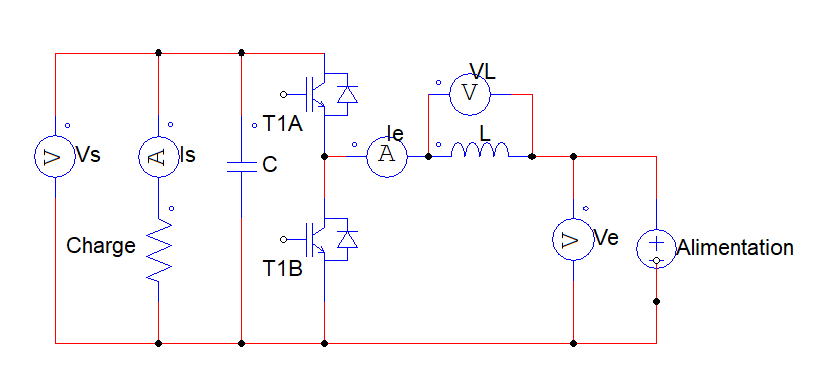

*Schéma de cablage du bloc de puissance en mode "Hacheur parallele".*

### Mesures de valeurs moyennes

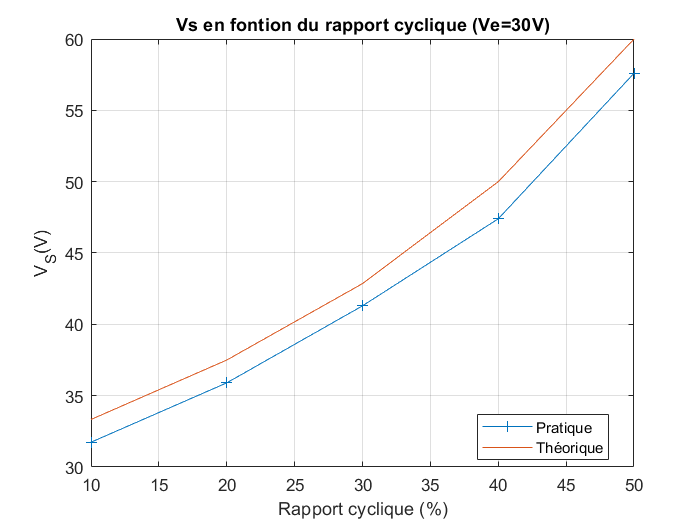

alpha=[0.1 0.20 0.30 0.40 0.50]*100;
Vs=[31.74 35.9 41.3 47.4 57.6];
Ie=[2.29 2.61 2.91 3.41 4.08];
Is=2;
Ve=30;
Ps=Vs.*Is;
Pe=Ve.*Ie;

Vsth=(100.*Ve)./(100-alpha);%%Pour avoir alpha en pourcentage en absscice, il faut multiplier la formulule par cent au dénominateur et au numérateur
rendement_th=[100 100 100 100 100];

plot(alpha,Vs,'+-',alpha,Vsth);
title("Vs en fontion du rapport cyclique (Ve=30V)");
xlabel("Rapport cyclique (%)"); ylabel("V_S(V)");
legend('Pratique','Théorique','Location','best');
grid on;

On peut observer que l'allure de la courbe de la tension Vs en fonction du rendement pour un Ve constant est identique à celle pour le hacheur série dans les mêmes circonstances.

En effet, on a Vs = (1+α)*Ve. Nous n'avons pas tracé pour un rapport cyclique nul car Vs est également nul. Aussi, utilisé un rendement supérieur à 50% risquait de détruire le bloc de puissance, c'est pourquoi nous nous sommes arretés à 50%.

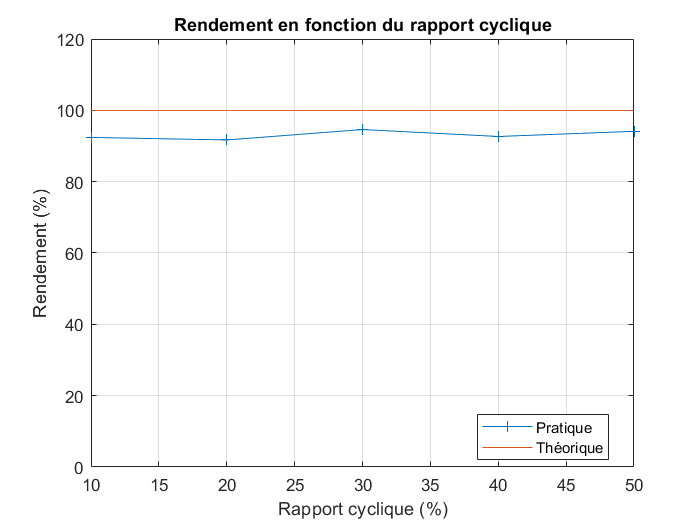

plot(alpha,Ps./Pe *100,'+-',alpha,rendement_th);
title("Rendement en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("Rendement (%)");
legend('Pratique','Théorique','Location','best');
ylim([0 120])
grid on;

Puisque le bloc de convertion est un hacheur, alors il est normal d'avoir rendement quasi-constant.

Les transistors utilisés pour les convertisseurs sont de type IGBT.

### Mesures temporelles

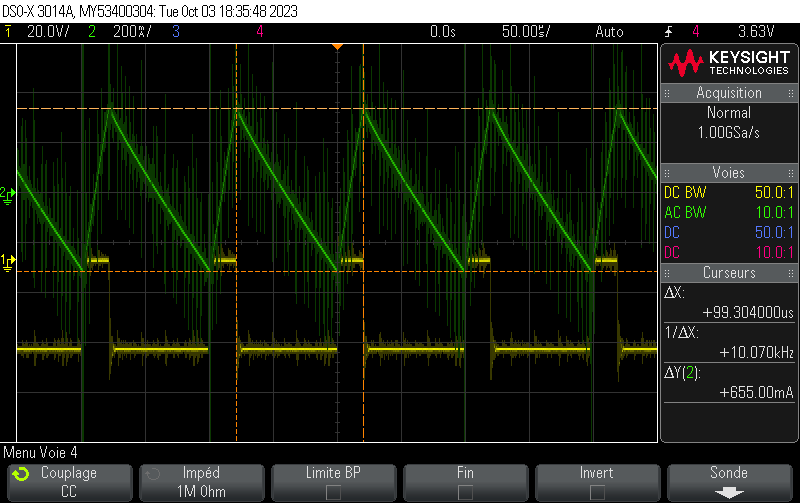

Rapport cyclique : 20%

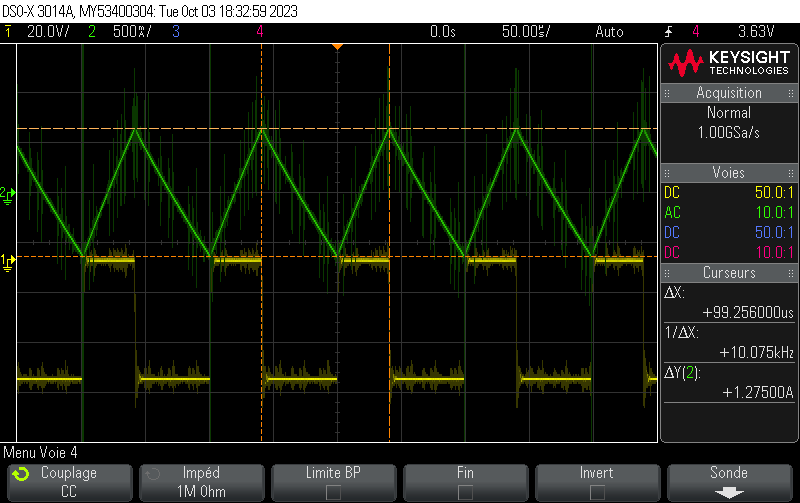

Rapport cyclique : 40%

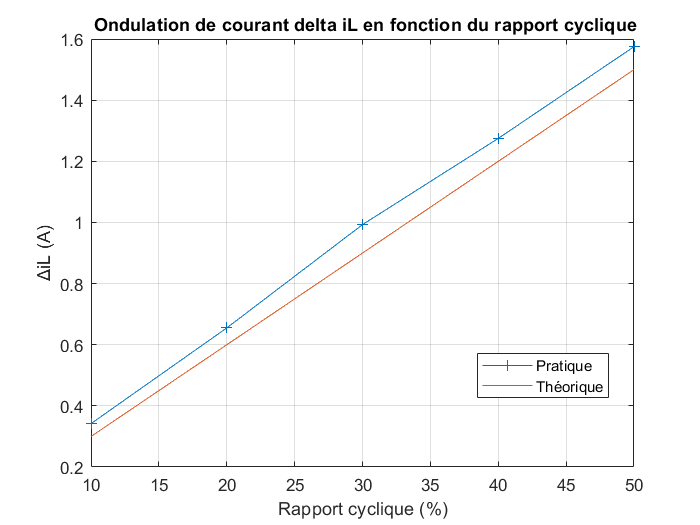

alpha=[0.1 0.20 0.30 0.40 0.50]*100;
Delta_iL=[342 655 993 1275 1575]*1e-3;
Delta_il_th=((alpha./100).*Ve)./(1e-3*10e3);

plot(alpha,Delta_iL,'+-',alpha,Delta_il_th);
legend('Pratique','Théorique','Location','best');
title(" Ondulation de courant delta iL en fonction du rapport cyclique");
xlabel("Rapport cyclique (%)"); ylabel("ΔiL (A)");
grid on

Les valeurs expérimentales ont la même allure que les valeurs théoriques, mais dévient plus le rapport cyclique augmente.

Plus le rapport cyclique est élevé, plus la différence entre la tension max et min de iL est élevé. Quand α augmente, la tension Us augmente également et donc réciproquement, le courant iL augmente. Le ΔiL est également amplifié. 

## 3. Complément: Conduction discontinue

### Hacheur Série

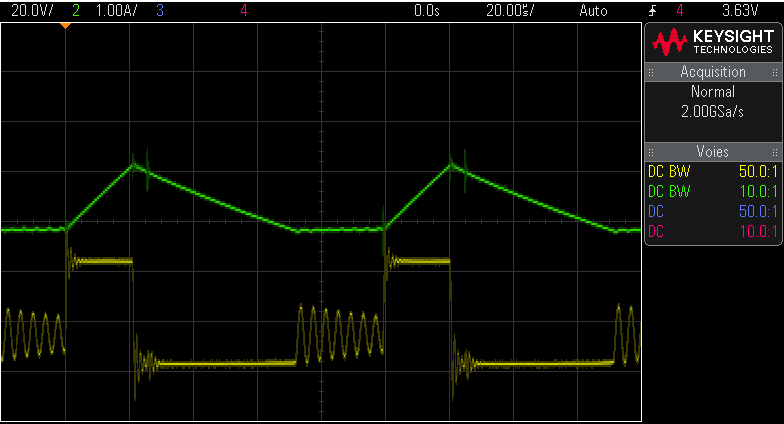

### Hacheur Parallèle

# 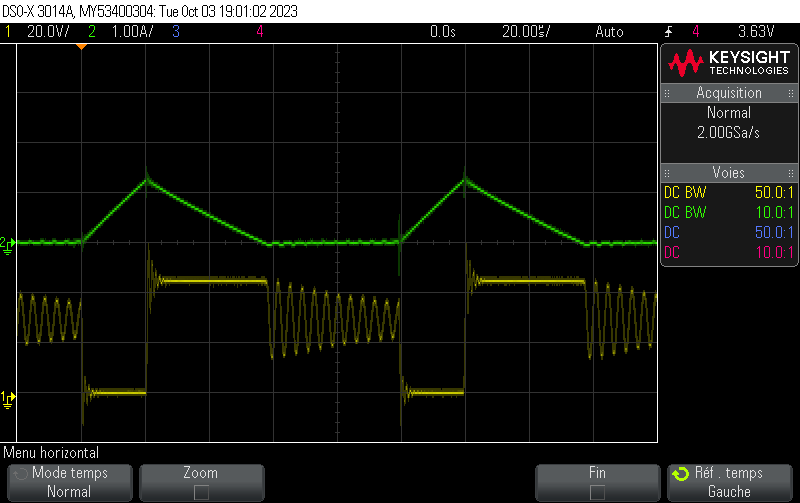

La discontinuité est une anomalie de fonctionnement du hacheur parallèle : ce phénomène s'explique par la décharge complète de la tension présente dans la bobine avant que la période complète soit finie. Cela a pour conséquence que la tension Vs, qui est la somme de Ve et VL, oscille. L'oscillation est causée par les capacités parasites en série avec la bobine.